%% Motor speed calibration: fit RPM vs. motor command
clear; clc; close all;
 
% Measured data (command 30 was in the deadzone, so it is not included)
cmd = [40 50 60 100 200 255];
rpm = [62 80 100 180 368 453];
 
% Linear least-squares fit: RPM = m*cmd + b
p = polyfit(cmd, rpm, 1);
m = p(1)

m = 1.8437

b = p(2)

b = -9.4737


plot(cmd, rpm, 'DisplayName', "Original");
x_list = linspace(0, 255, 250); hold on
y_list = m*x_list + b

y_list =    -9.4737   -7.5856   -5.6974   -3.8092   -1.9210   -0.0328    1.8553    3.7435    5.6317    7.5199    9.4080   11.2962   13.1844   15.0726   16.9607   18.8489   20.7371   22.6253   24.5134   26.4016   28.2898   30.1780   32.0661   33.9543   35.8425   37.7307   39.6188   41.5070   43.3952   45.2834   47.1715   49.0597   50.9479   52.8361   54.7242   56.6124   58.5006   60.3888   62.2769   64.1651   66.0533   67.9415   69.8297   71.7178   73.6060   75.4942   77.3824   79.2705   81.1587   83.0469


plot(x_list, y_list, 'DisplayName', "CurveFit");
h = legend()

h =   Legend (Original, CurveFit) with properties:

         String: {'Original'  'CurveFit'}
       Location: 'northeast'
    Orientation: 'vertical'
       FontSize: 9
       Position: [0.7127 0.7987 0.1739 0.0939]
          Units: 'normalized'

  Show all properties


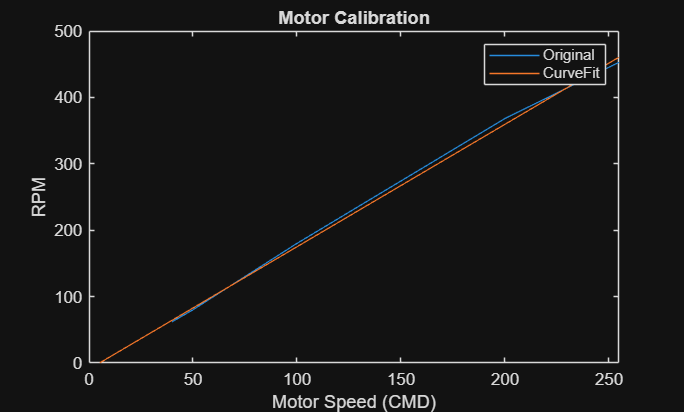

xlabel("Motor Speed (CMD)")
ylabel("RPM")
title("Motor Calibration")
xlim([0 255])
ylim([0 500])